## The ADI Method

g = @(x, y, t) exp(3*t/2).*sin(1/2*(x-y)).*cosh(x+y);
u_0 = @(x, y) sin(1/2*(x-y)).*cosh(x+y);
t_N = 1;
u_exact = @(x, y, t) exp(3*t/2) * sin(1/2*(x-y)).*cosh(x+y);
p = 0:4;
h_vals = 0.1 * 2.^(-p);
err = zeros(length(h_vals), 3);

for i = 1:length(h_vals)

    % spacial discretization
    h = h_vals(i);
    
    % temporal discretization
    k = h;
    x = 0:h:1;
    y = 0:h:1; 
    
    m = length(x)-1;
    
    [X, Y] = ndgrid(x, y);
    
    U_exact = u_exact(X, Y, t_N);

    U_init = u_0(X(2:end-1, 2:end-1), Y(2:end-1, 2:end-1)); % grid of only interior points

    U_ADI = ADI(U_init, g, h, k, t_N);

    err(i, 1) = h;
    err(i, 2) = max(abs(U_exact - U_ADI), [], 'all'); % error calculation
    if i ~= 1
        err(i, 3) = log2(err(i-1, 2)./err(i, 2)); % order calculation
    else
        err(i, 3) = nan;
    end
end

T = array2table(err);
T.Properties.VariableNames = {'Step Size', 'Error', 'Numerical Order'};
disp(T)

    Step Size      Error       Numerical Order
    _________    __________    _______________

         0.1     0.00014664           NaN     
        0.05     3.8157e-05        1.9422     
       0.025     9.7128e-06         1.974     
      0.0125     2.4337e-06        1.9967     
     0.00625     6.0901e-07        1.9986     



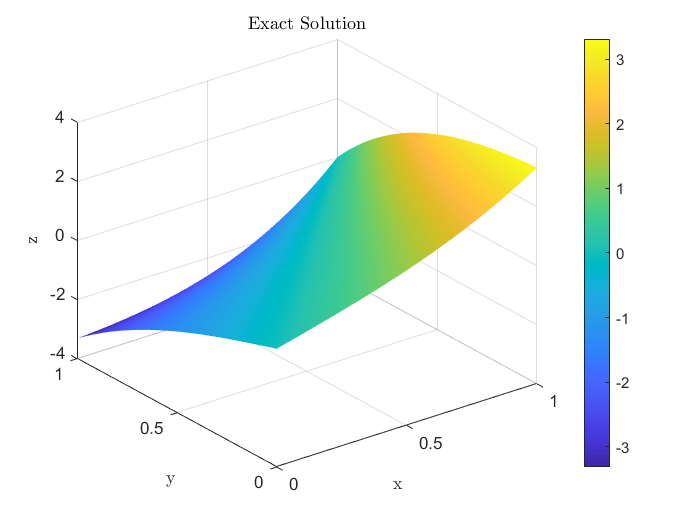

figure; clf
interior_msk = (X ~= 0 & X~= 1) & (Y ~= 0 & Y~= 1);
surf(X, Y, U_exact); shading interp
colorbar
title("Exact Solution", "Interpreter", "latex")
xlabel("x", "Interpreter", "latex");
ylabel("y", "Interpreter", "latex");
zlabel("z", "Interpreter", "latex");

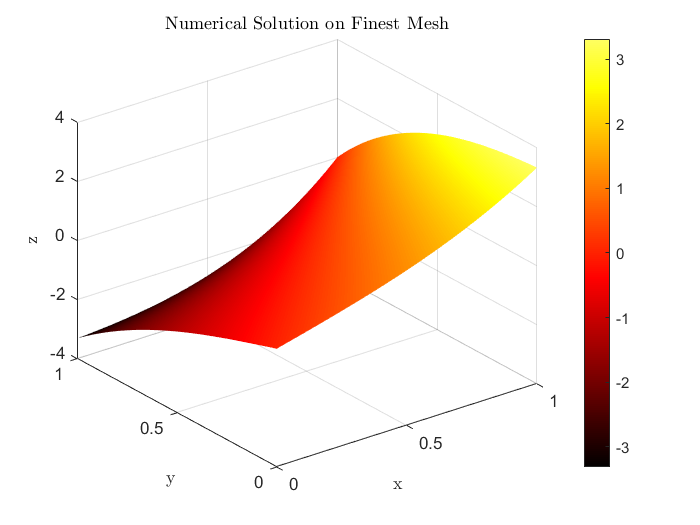


figure; clf
interior_msk = (X ~= 0 & X~= 1) & (Y ~= 0 & Y~= 1);
surf(X, Y, U_ADI); shading interp

% color map
cm = hot(256);
cm = cm(1:end-40, :); % truncate off last few rows
colormap(cm) % apply truncated map
caxis([min(U_ADI(:))   max(U_ADI(:))]) % restore the original caxis
colorbar
title("Numerical Solution on Finest Mesh", "Interpreter", "latex")
xlabel("x", "Interpreter", "latex");
ylabel("y", "Interpreter", "latex");
zlabel("z", "Interpreter", "latex");

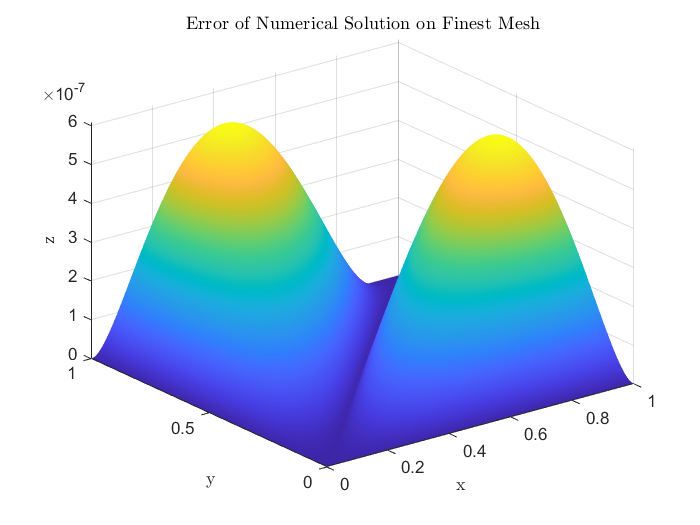



figure; clf
surf(X, Y, abs(U_exact -  U_ADI)); shading interp
title("Error of Numerical Solution on Finest Mesh", "Interpreter", "latex");
xlabel("x", "Interpreter", "latex");
ylabel("y", "Interpreter", "latex");
zlabel("z", "Interpreter", "latex");